% For a transformation matrix T:
%position = T(1:3, 4);          % [x; y; z]
%rotation = T(1:3, 1:3);        % 3x3 rotation matrix
disp('X, Y, Z')

X, Y, Z


disp('Frame 0:');

Frame 0:


disp(frame0XYZ)

  -20.0000   -2.0200         0



disp('Frame 1:');

Frame 1:


disp(frame1XYZ)

  -20.0000   -2.0200         0



disp('Frame 2:');

Frame 2:


disp(frame2XYZ)

  -20.0000  -13.9135   11.8935



disp('Frame 3:');

Frame 3:


disp(frame3XYZ)

  -20.0000    2.1892   17.6179



disp('Frame 4:');

Frame 4:


disp(frame4XYZ)

  -20.0000    2.1892   17.6179



disp('Frame 5:');

Frame 5:


disp(frame5XYZ)

  -20.0000    2.1892   17.6179



disp('End Effector Position:'); 

End Effector Position:


disp(frame6XYZ); 

   -0.2152   -0.5116   16.4924




disp('Frame 0p:');

Frame 0p:


disp(frame0pXYZ)

   20.0000   -2.0200         0



disp('Frame 1p:');

Frame 1p:


disp(frame1pXYZ)

   20.0000   -2.0200         0



disp('Frame 2p:');

Frame 2p:


disp(frame2pXYZ)

   20.0000  -16.5865    8.4100



disp('Frame 3p:');

Frame 3p:


disp(frame3pXYZ)

   20.0000   -2.1892   17.6179



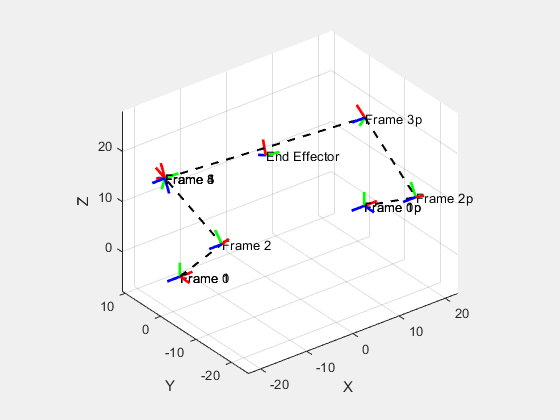


figure;
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
view(3);

% Plot frames and links
transformation_matrices = {Tb_0, Tb_1, Tb_2, Tb_3, Tb_4, Tb_5, Tb_6, Tb_3p, Tb_2p, Tb_1p, Tb_0p};
frame_labels = {'Frame 0', 'Frame 1', 'Frame 2', 'Frame 3', 'Frame 4', 'Frame 5', 'End Effector', 'Frame 3p', 'Frame 2p', 'Frame 1p', 'Frame 0p'};

% Plot each frame
for i = 1:length(transformation_matrices)
    plotFrame(transformation_matrices{i}, frame_labels{i}, 3);
end
% Extract origins as Nx3 matrix (each row: [x, y, z])
origins = cellfun(@(T) T(1:3, 4)', transformation_matrices, 'UniformOutput', false);
origins = vertcat(origins{:}); 

% Connect origins with lines, excluding the lines between frame 5 to frame 6 and frame 6 to frame 3p
% Instead, draw a line directly between frame 5 and frame 3p
plot3(origins(1:5,1), origins(1:5,2), origins(1:5,3), 'k--', 'LineWidth', 1.5); % Connect frames 0 to 5
plot3(origins(8:end,1), origins(8:end,2), origins(8:end,3), 'k--', 'LineWidth', 1.5); % Connect frames 3p to 0p
plot3([origins(5,1), origins(8,1)], [origins(5,2), origins(8,2)], [origins(5,3), origins(8,3)], 'k--', 'LineWidth', 1.5); % Connect frame 5 to frame 3p

% Debugging
%disp(size(origins)); % Should output 4x3 (for 4 transformation matrices)

% Comment this line out if you don't want to generate a popup 3d figure
set(gcf,'Visible','on')

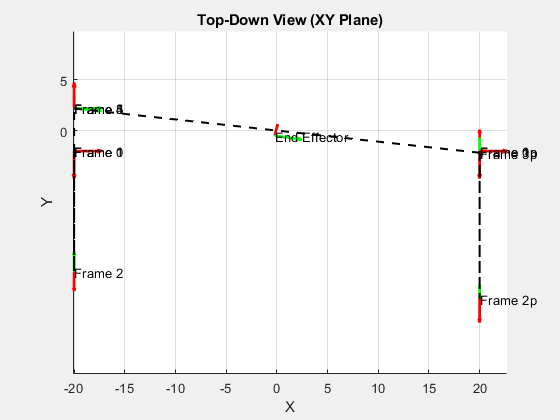


function plotFrame(T, label, axis_length)
    % Extract position and orientation
    position = T(1:3, 4);
    rotation = T(1:3, 1:3);
    
    % Define axis directions (scaled for visibility)
    X_axis = rotation(:,1) * axis_length;
    Y_axis = rotation(:,2) * axis_length;
    Z_axis = rotation(:,3) * axis_length;
    
    % Plot axes
    quiver3(position(1), position(2), position(3), X_axis(1), X_axis(2), X_axis(3), 'r', 'LineWidth', 2);
    quiver3(position(1), position(2), position(3), Y_axis(1), Y_axis(2), Y_axis(3), 'g', 'LineWidth', 2);
    quiver3(position(1), position(2), position(3), Z_axis(1), Z_axis(2), Z_axis(3), 'b', 'LineWidth', 2);
    
    % Label the frame
    text(position(1), position(2), position(3), label, 'FontSize', 10, 'Color', 'k');
end

%--------------------------------------------------

% Create a new figure for the XY plane "top-down" view
figure;
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y');
view(2); % Top-down view
title('Top-Down View (XY Plane)');

% Plot frames and links
transformation_matrices = {Tb_0, Tb_1, Tb_2, Tb_3, Tb_4, Tb_5, Tb_6, Tb_3p, Tb_2p, Tb_1p, Tb_0p};
frame_labels = {'Frame 0', 'Frame 1', 'Frame 2', 'Frame 3', 'Frame 4', 'Frame 5', 'End Effector', 'Frame 3p', 'Frame 2p', 'Frame 1p', 'Frame 0p'};

% Plot each frame
for i = 1:length(transformation_matrices)
    plotFrame2D(transformation_matrices{i}, frame_labels{i}, 3);
end

% Extract x and y coordinates (ignore z)
origins_2D = cellfun(@(T) T(1:2, 4)', transformation_matrices, 'UniformOutput', false);
origins_2D = vertcat(origins_2D{:});

% Extract x and y coordinates (ignore z)
origins_2D = cellfun(@(T) T(1:2, 4)', transformation_matrices, 'UniformOutput', false);
origins_2D = vertcat(origins_2D{:});

% Connect origins with lines, excluding the lines between frame 5 to frame 6 and frame 6 to frame 3p
% Instead, draw a line directly between frame 5 and frame 3p
plot(origins_2D(1:5,1), origins_2D(1:5,2), 'k--', 'LineWidth', 1.5); % Connect frames 0 to 5
plot(origins_2D(8:end,1), origins_2D(8:end,2), 'k--', 'LineWidth', 1.5); % Connect frames 3p to 0p
plot([origins_2D(5,1), origins_2D(8,1)], [origins_2D(5,2), origins_2D(8,2)], 'k--', 'LineWidth', 1.5); % Connect frame 5 to frame 3p

% Hide Z-axis
set(gca, 'ZTick', []);

% Comment this line out if you don't want to generate a popup XY figure
set(gcf,'Visible','on')

% ====== Choose Tick Spacing ====== %
% Use these to compute data ranges by solved value ranges
% x_min = min(origins_2D(:,1));
% x_max = max(origins_2D(:,1));
% y_min = min(origins_2D(:,2));
% y_max = max(origins_2D(:,2));

% Or just show overall range of workspace
x_min = -25;
x_max = 25;
y_min = 0;
y_max = 50;

% Define a common step size ~5 is good
step = 5;

% Generate ticks for both axes
x_ticks = floor(x_min/step)*step : step : ceil(x_max/step)*step;
y_ticks = floor(y_min/step)*step : step : ceil(y_max/step)*step;

% Set ticks
xticks(x_ticks);
yticks(y_ticks);

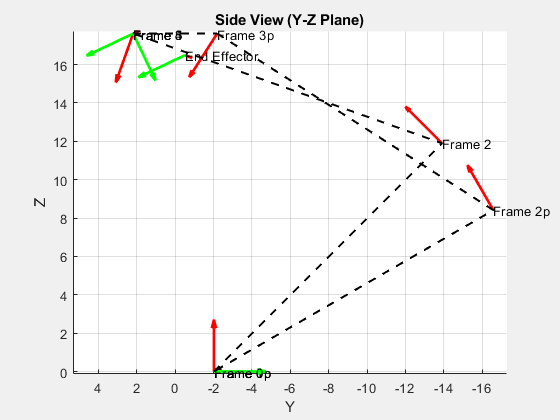

% ==================================== %

% ==== Y-Z Plane Side View ==== %
figure;
hold on; grid on; axis equal;
xlabel('Y'); ylabel('Z'); % Y on x-axis, Z on y-axis
set(gca, 'XDir','reverse');
title('Side View (Y-Z Plane)');

% Plot frames and links
transformation_matrices = {Tb_0, Tb_1, Tb_2, Tb_3, Tb_4, Tb_5, Tb_6, Tb_3p, Tb_2p, Tb_1p, Tb_0p};
frame_labels = {'Frame 0', 'Frame 1', 'Frame 2', 'Frame 3', 'Frame 4', 'Frame 5', 'End Effector', 'Frame 3p', 'Frame 2p', 'Frame 1p', 'Frame 0p'};

% Plot each frame (Y-Z projection)
for i = 1:length(transformation_matrices)
    plotFrameYZ(transformation_matrices{i}, frame_labels{i}, 3);
end

% Extract Y and Z coordinates
origins_YZ = cellfun(@(T) [T(2, 4), T(3, 4)], transformation_matrices, 'UniformOutput', false);
origins_YZ = vertcat(origins_YZ{:});

% Connect origins with lines, excluding the lines between frame 5 to frame 6 and frame 6 to frame 3p
% Instead, draw a line directly between frame 5 and frame 3p
plot(origins_YZ(1:5,1), origins_YZ(1:5,2), 'k--', 'LineWidth', 1.5); % Connect frames 0 to 5
plot(origins_YZ(8:end,1), origins_YZ(8:end,2), 'k--', 'LineWidth', 1.5); % Connect frames 3p to 0p
plot([origins_YZ(5,1), origins_YZ(8,1)], [origins_YZ(5,2), origins_YZ(8,2)], 'k--', 'LineWidth', 1.5); % Connect frame 5 to frame 3p

% Comment this line out if you don't want to generate a popup YZ figure
set(gcf,'Visible','on')

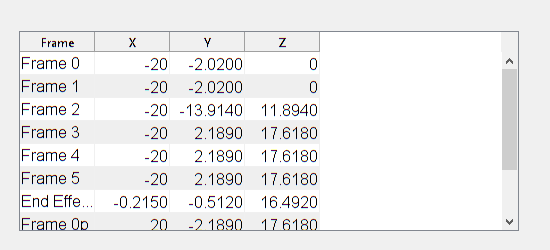


function plotFrameYZ(T, label, axis_length)
    % Extract position and orientation
    position = T(1:3, 4);
    rotation = T(1:3, 1:3);
    
    % Project axes onto Y-Z plane (Y on x-axis, Z on y-axis)
    Y_axis_YZ = [rotation(2,2), rotation(3,2)] * axis_length; % Y on x-axis
    Z_axis_YZ = [rotation(2,3), rotation(3,3)] * axis_length; % Z on y-axis
    
    % Plot axes
    quiver(position(2), position(3), Y_axis_YZ(1), Y_axis_YZ(2), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    quiver(position(2), position(3), Z_axis_YZ(1), Z_axis_YZ(2), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Label the frame
    text(position(2), position(3), label, 'FontSize', 10, 'Color', 'k');
end

function plotFrame2D(T, label, axis_length)
    % Extract position and orientation
    position = T(1:3, 4);
    rotation = T(1:3, 1:3);
    
    % Project axes onto XY plane (ignore Z)
    X_axis_2D = rotation(1:2,1) * axis_length; % Extract X and Y components
    Y_axis_2D = rotation(1:2,2) * axis_length;
    
    % Plot axes (quiver for 2D)
    quiver(position(1), position(2), X_axis_2D(1), X_axis_2D(2), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    quiver(position(1), position(2), Y_axis_2D(1), Y_axis_2D(2), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    
    % Label the frame
    text(position(1), position(2), label, 'FontSize', 10, 'Color', 'k');
end
% ==== Create a Separate Figure for the Table ==== %
fig = figure('Name', 'Frame Coordinates', 'NumberTitle', 'off', ...
             'MenuBar', 'none', 'ToolBar', 'none'); % Remove menu and toolbar
axes('Visible', 'off'); % Hide axes

% Extract coordinates
frame_names = {'Frame 0', 'Frame 1', 'Frame 2', 'Frame 3', 'Frame 4', 'Frame 5', 'End Effector', 'Frame 0p', 'Frame 1p', 'Frame 2p', 'Frame 3p'};
coordinates = cellfun(@(T) T(1:3, 4)', transformation_matrices, 'UniformOutput', false);
coordinates = vertcat(coordinates{:}); % Convert to Nx3 matrix
coordinates = round(coordinates, 3); % Round to 3 decimals

% Create table data
table_data = [frame_names(:), num2cell(coordinates)]; % Combine names and coordinates
column_names = {'Frame', 'X', 'Y', 'Z'}; % Column headers

% Create uitable
t = uitable(fig, 'Data', table_data, 'ColumnName', column_names, 'RowName', [], ...
            'Position', [20 20 500 200], 'FontSize', 12);

% Adjust figure size to fit the table
fig.Position(3:4) = [550 250]; % [width height]

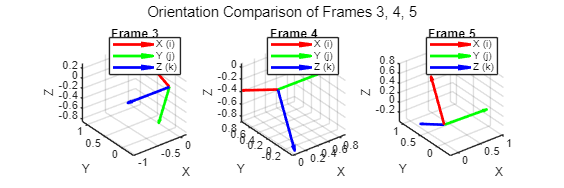

% ==== Individual Frame Orientation Comparison ==== %
figure('Name', 'Frame Orientations (3, 4, 5)', 'Position', [100 100 1200 400]);

% Frames to compare
frames_to_plot = [4, 5, 6]; % MATLAB indices for Tb_3, Tb_4, Tb_5 (since Tb_0 is index 1)
frame_labels = {'Frame 3', 'Frame 4', 'Frame 5'};

% Plot each frame in a subplot
for i = 1:length(frames_to_plot)
    idx = frames_to_plot(i);
    T = transformation_matrices{idx};
    
    subplot(1, 3, i);
    hold on; grid on; axis equal;
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title(frame_labels{i});
    view(3);
    
    % Extract rotation matrix
    rotation = T(1:3, 1:3); % 3x3 rotation matrix
    
    % Plot axes with labels (apply rotation)
    quiver3(0, 0, 0, rotation(1,1), rotation(2,1), rotation(3,1), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.3); % X (i)
    quiver3(0, 0, 0, rotation(1,2), rotation(2,2), rotation(3,2), 'g', 'LineWidth', 2, 'MaxHeadSize', 0.3); % Y (j)
    quiver3(0, 0, 0, rotation(1,3), rotation(2,3), rotation(3,3), 'b', 'LineWidth', 2, 'MaxHeadSize', 0.3); % Z (k)
    
    % Add legend
    legend({'X (i)', 'Y (j)', 'Z (k)'}, 'Location', 'northeast');
end

% Add super-title
sgtitle('Orientation Comparison of Frames 3, 4, 5');